%微分方程的三种方法
%第二种计算方法ode家族，下面为ode45
[t,y] = ode45(@ep2,[0 20],[2; 0]);%方程组写在ep2,参数一：方程；二：取值范围
plot(t,y(:,1),'-o',t,y(:,2),'-o')
title('Solution of van der Pol Equation (\mu = 1) with ODE45');
xlabel('Time t');
ylabel('Solution y');
legend('y_1','y_2')

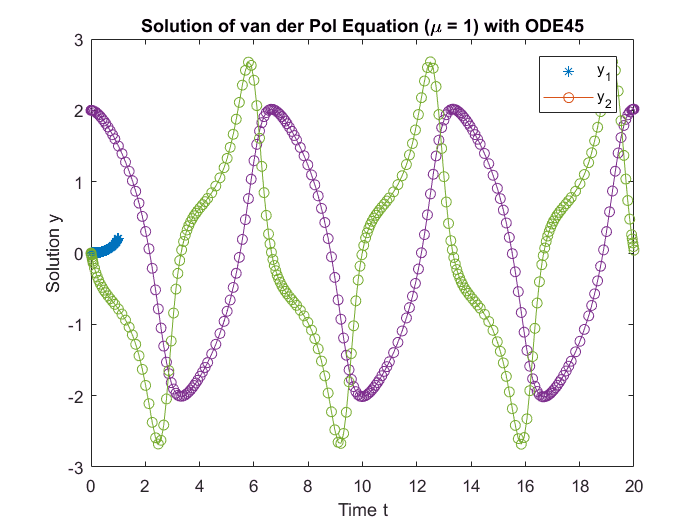

%第一种方法desolve

syms x y%定义变量
y=dsolve('x*Dy+y-exp(x)=0','y(1)=2*exp(1)','x')%参数一：方程，参数二：初值，参数三：自变量

$$y = \frac{\mathrm{e}+{\mathrm{e}}^{x}}{x}$$

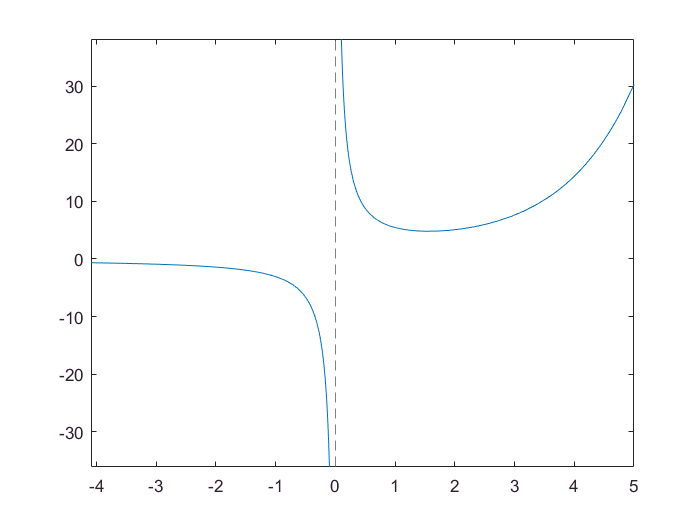

fplot(y)%简单画图

%pde标准形式
x=0:0.05:1;t=0:0.05:2;m=0;
sol=pdepe(m,@pdefun,@pdeic,@pdebc,x,t);

Error: File: pdebc.m Line: 1 Column: 43
Unexpected MATLAB operator.

Error in pdepe (line 250)
[pL,qL,pR,qR] = feval(bc,xmesh(1),y0(:,1),xmesh(nx),y0(:,nx),t(1),varargin{:});

u1=sol(:,:,1);
u2=sol(:,:,2);
figure;
surf(x,t,u1)
title('u1(x,t)')
xlabel('Distance x')
ylabel('Time t')
figure;
surf(x,t,u2)
title('u2(x,t)')
xlabel('Distance x')
ylabel('Time t')

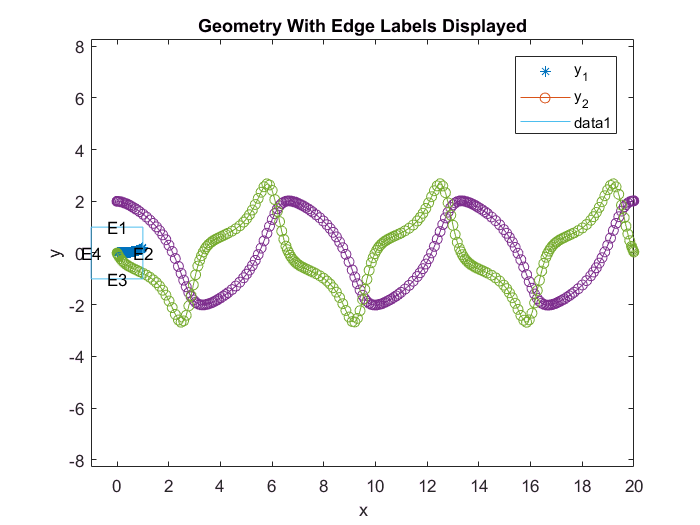

%第三种偏微分（注意查看相关求解器）
 c = 1;
a = 0;
f = 0;
m = 1;
numberOfPDE = 1;
model = createpde(numberOfPDE);
geometryFromEdges(model,@squareg);
pdegplot(model,'EdgeLabels','on');
ylim([-1.1 1.1]);
axis equal
title('Geometry With Edge Labels Displayed');
xlabel('x')
ylabel('y')

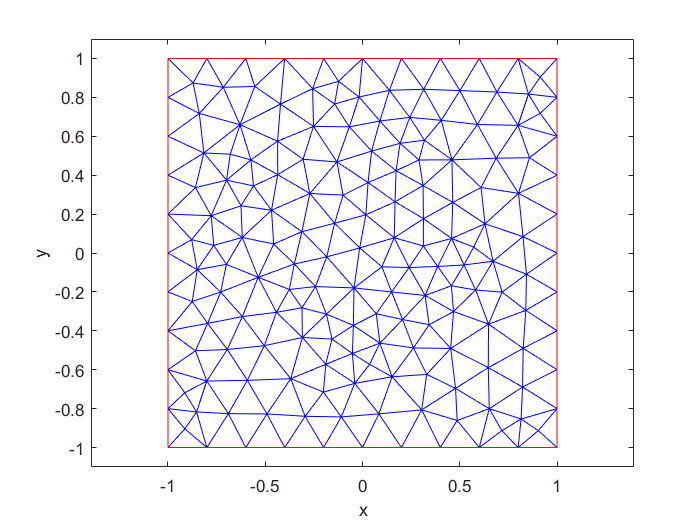

specifyCoefficients(model,'m',m,'d',0,'c',c,'a',a,'f',f);
applyBoundaryCondition(model,'dirichlet','Edge',[2,4],'u',0);
applyBoundaryCondition(model,'neumann','Edge',([1 3]),'g',0);
generateMesh(model);
figure
pdemesh(model);
ylim([-1.1 1.1]);
axis equal
xlabel('x')
ylabel('y')

u0 = @(location) atan(cos(pi/2*location.x));
ut0 = @(location) 3*sin(pi*location.x).*exp(sin(pi/2*location.y));
setInitialConditions(model,u0,ut0);
n = 31;% 求解次数
tlist = linspace(0,5,n);
model.SolverOptions.ReportStatistics ='on';
result = solvepde(model,tlist);

428 successful steps
62 failed attempts
982 function evaluations
1 partial derivatives
142 LU decompositions
981 solutions of linear systems


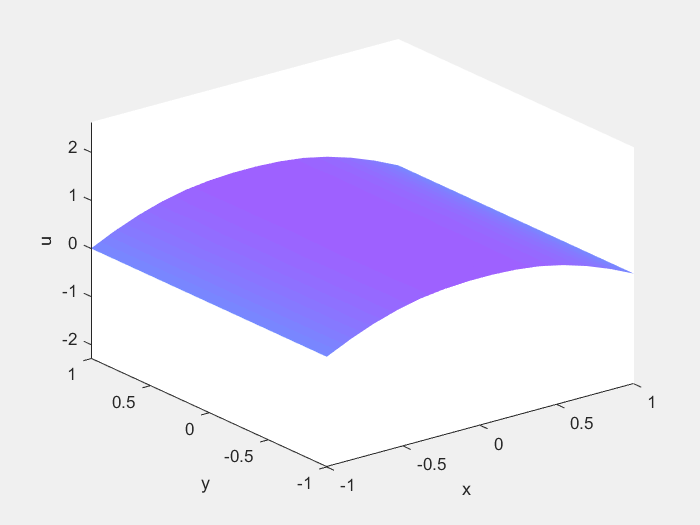

u = result.NodalSolution;
figure

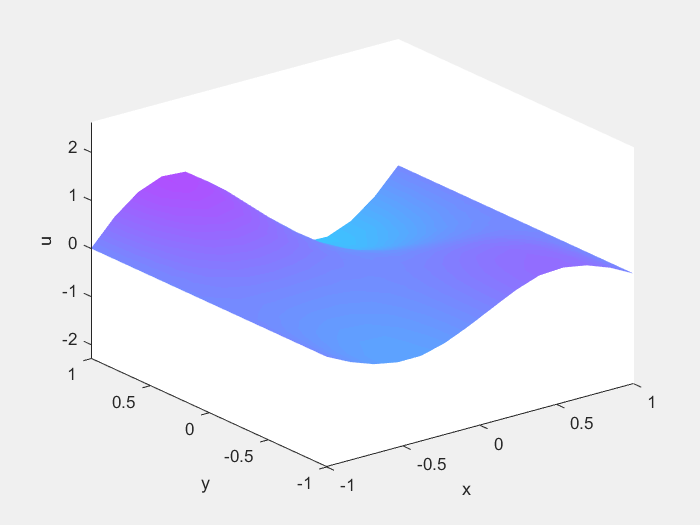

umax = max(max(u));
umin = min(min(u));
for i = 1:n
    pdeplot(model,'XYData',u(:,i),'ZData',u(:,i),'ZStyle','continuous',...
        'Mesh','off','XYGrid','on','ColorBar','off');
    axis([-1 1 -1 1 umin umax]);
    caxis([umin umax]);
    xlabel x
    ylabel y
    zlabel u
    M(i) = getframe;
end